- Load training and test data

clc; clear all;
iris=load('training.mat');
test=load('testing.mat');

Train_data=[iris.Petal_length;iris.Petal_width;iris.Sepal_length;iris.Sepal_width;iris.label];


Test_data=[test.Petal_length_test;test.Petal_width_test;test.Sepal_length_test;test.Sepal_width_test];
label_test=test.label_test;

2. Get the possible predictions from the data

choice=[];
for i=1:length(Train_data)
find_mle=Train_data(end,i);
if sum(choice==find_mle)==0
choice=[choice find_mle];
end
end
choice=sort(choice)

choice =      0     1     2


3. Find the prior distributions for each possible prediction choices

 prior=[];
 for i=1:length(choice)
 probability=sum(iris.label==choice(i))/length(iris.label);
 prior=[prior probability];
 
 end
 display(prior)

prior =     0.3250    0.3250    0.3500


4. Group the data by possible choice

 separated_data={};
T_data=[];
for i=1:length(choice)
for j=1:length(Train_data)
if Train_data(end,j)==choice(i)
  T_data=[T_data Train_data(:,j)];  
end
end
separated_data{i}=T_data;
T_data=[];
end
display(separated_data)

separated_data = 1×3 cell array
    {5×39 double}    {5×39 double}    {5×42 double}


5. Make predictions

Prediction=[];
i1=1;
keep2={};
keep=[];
k1=1;
for i=1:length(Test_data) % Itirate over test data
tdata=Test_data(:,i); % load test individual data 
find_mle=1;
mle=[];

estimates=[];
j1=1;

for j=1:length(separated_data)   % Itirate over different groups 
   r=separated_data{1,j};
 for i=1:1:length(tdata)     % Itirate over different attributes
    
  % Use gaussian distribution to calculate likelihoods
  
  likelihood=(1/(sqrt(2*pi*std(r(i,:)))))*exp(-((tdata(i)-mean(r(i,:)))^2)/(2*std(r(i,:))^2));
  
X=[min(r(i,:)):0.1:max(r(i,:))];
Y=(1/(sqrt(2*pi*std(r(i,:)))))*exp(-((X-mean(r(i,:))).^2)/(2*std(r(i,:))^2));
keep1=[X;Y];
Keep2{k1}=keep1;
k1=k1+1;
keep=[keep;tdata(i),likelihood ];



 find_mle=find_mle*likelihood; % multiply the conditional probabilities 
 estimates=[estimates; likelihood];
 end 
 mle=[mle find_mle]; % Store the liklihoods
 estimates=[[estimates' find_mle]'];
 
 results{i1,j1}=estimates;
 j1=j1+1;
 %reset values
 find_mle=1;
 estimates=[];
end
 MAP=mle.*prior; % multiply the liklihoods with the priors to find maximum a posteriori
Prediction1=sum((MAP==max(MAP)).*choice); % Pick the Maximum aposteriori and make prediction
Prediction=[Prediction Prediction1];
i1=i1+1;
end

6. Calculate the accuracy rate and the error rate

accuracy_rate= sum(Prediction==label_test)/length(label_test)

accuracy_rate = 0.9333

error_rate=1-accuracy_rate

error_rate = 0.0667

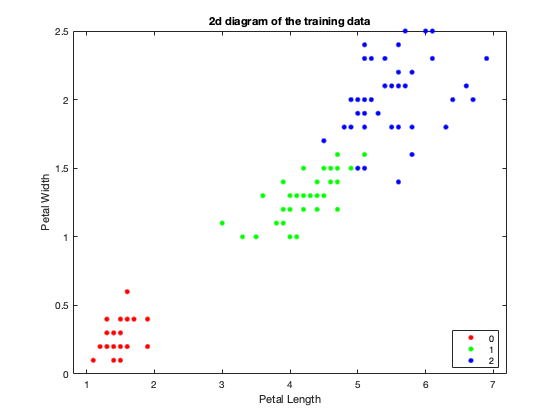

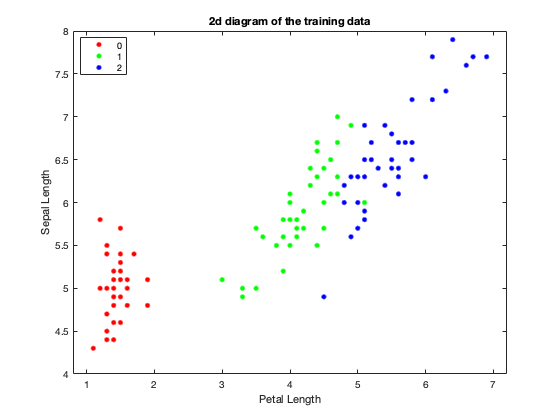

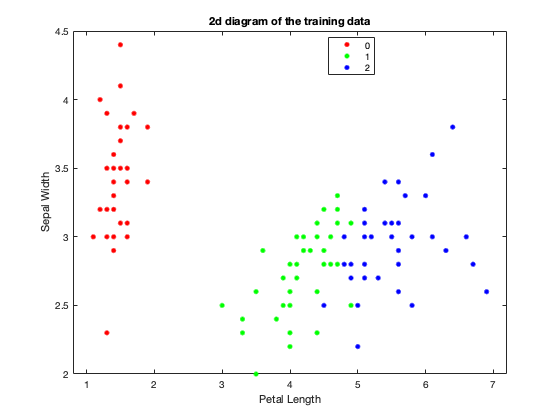

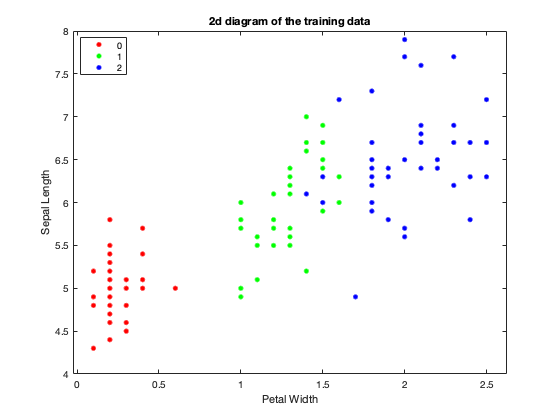

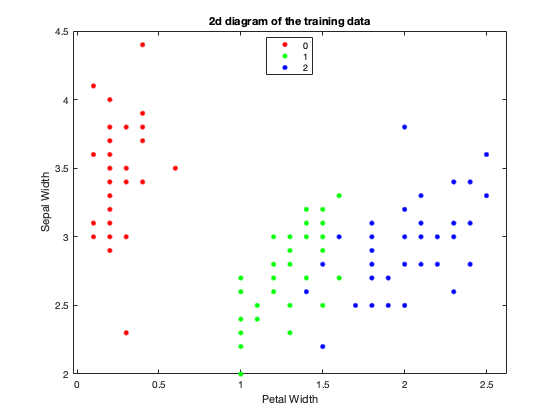

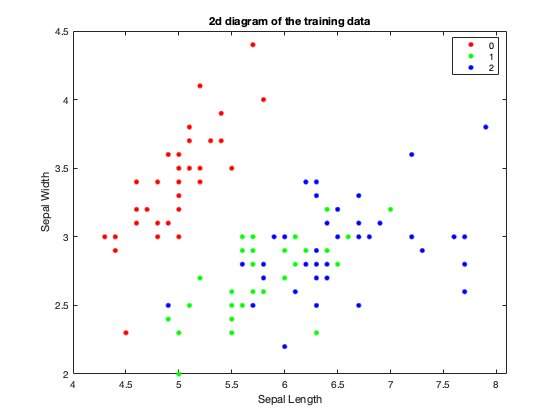

n1={'Petal Length','Petal Width', 'Sepal Length','Sepal Width'};

z=[1 2; 1 3; 1 4; 2 3; 2 4; 3 4];
for i=1:length(z)
figure(i),gscatter(Train_data(z(i,1),:),Train_data(z(i,2),:),Train_data(end,:));
xlabel(n1{z(i,1)})
ylabel(n1{z(i,2)})
title('2d diagram of the training data')
end

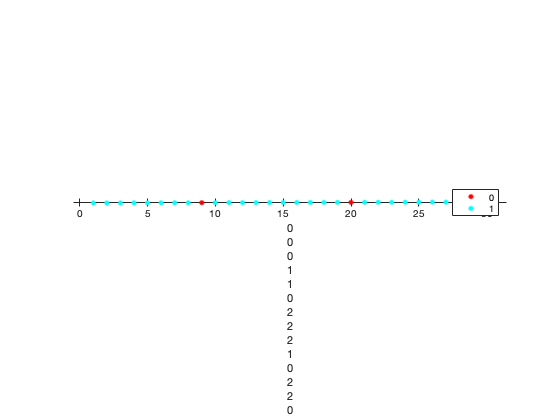

gscatter([1:1:length(Prediction)],[1:1:length(Prediction)], (Prediction==label_test))
legend('wrong','right')
%plot of the results

p1=[Prediction ; label_test ;(Prediction==label_test)] %predictions displayed

p1 =      0     0     0     1     1     0     2     2     2     1     0     2     2     0     1     0     0     1     2     2     2     0     1     0     1     2     1     2     1     0
     0     0     0     1     1     0     2     2     1     1     0     2     2     0     1     0     0     1     2     1     2     0     1     0     1     2     1     2     1     0
     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1


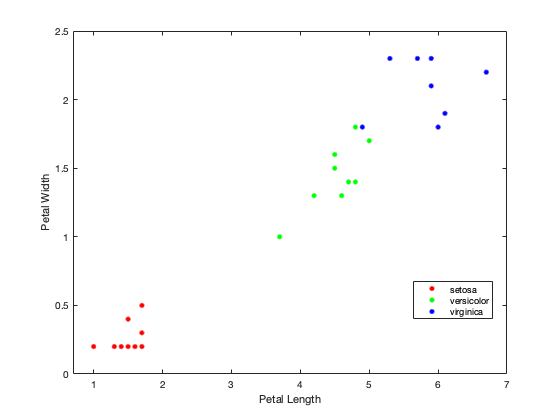

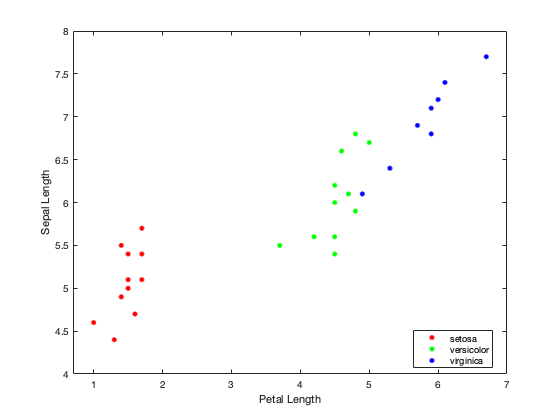

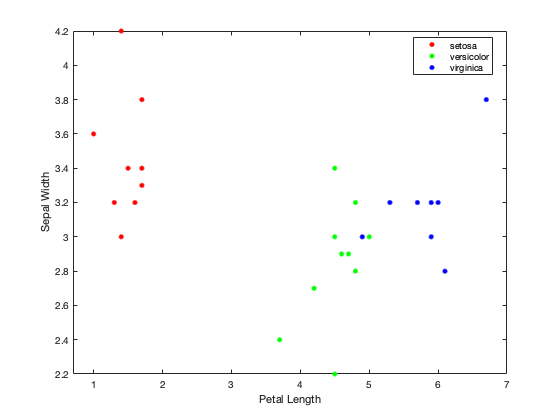

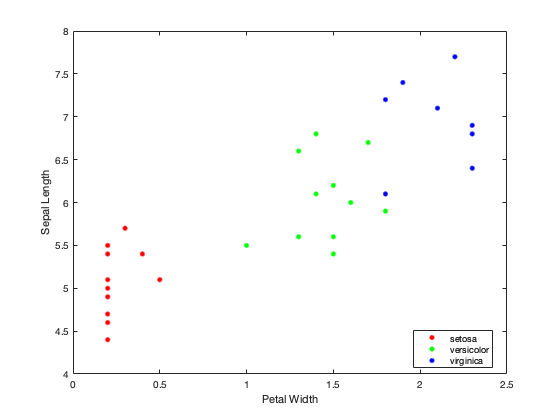

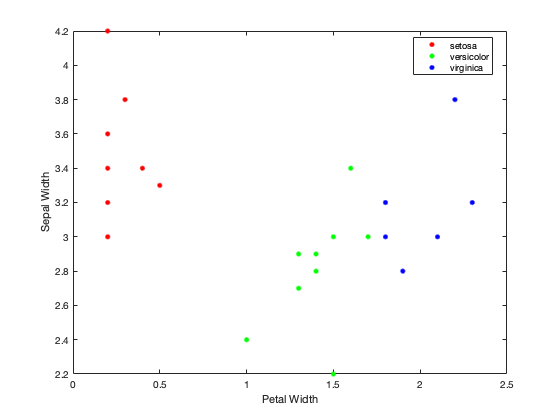

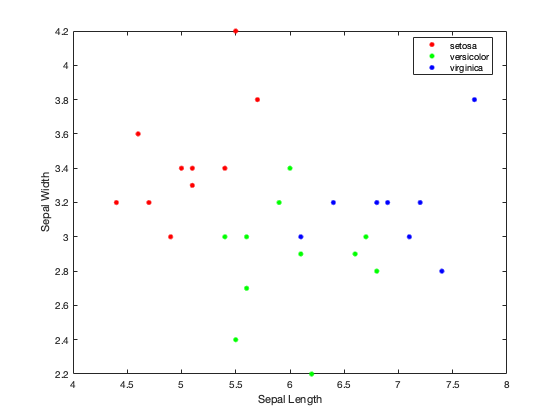

%2d diagram for test data
n1={'Petal Length','Petal Width', 'Sepal Length','Sepal Width'};

z=[1 2; 1 3; 1 4; 2 3; 2 4; 3 4];
for i=1:length(z)
figure(i),gscatter(Test_data(z(i,1),:),Test_data(z(i,2),:),label_test);
xlabel(n1{z(i,1)})
ylabel(n1{z(i,2)})
legend('setosa','versicolor','virginica')
end